## [Random Forest](https://apmonitor.com/pds/index.php/Main/RandomForest)

A random forest classifier is a machine learning algorithm that is used for classification tasks. It is an ensemble method that involves training multiple decision tree classifiers on subsets of the data and then averaging the predictions of all the individual classifiers to make a final prediction.

Random forest classifiers are often considered to be among the most accurate and robust machine learning algorithms, and they are widely used in a variety of applications, including image and text classification, fraud detection, and predictive maintenance.

A random forest classifier is a meta-estimator that fits a number of decision trees on various sub-samples of datasets and uses average to improve the predictive accuracy of the model and controls over-fitting. The sub-sample size is always the same as the original input sample size but the samples are drawn with replacement.

**Advantages:** Reduction in over-fitting and random forest classifier is more accurate than decision trees in most cases.

**Disadvantages:** Slow real-time prediction, difficult to implement, and complex algorithm.

In the following code, the Random Forest Classifier is used to create a random forest classifier. The classifier is then trained on a dataset of labeled training data (represented by the *X_Train* and Y*_Train* variables) using the *fit* method. The classifier can then be used to make predictions on new data (represented by the *X_Test* variable) using the *predict* method. Finally, the performance of the classifier can be evaluated by comparing its predictions to the true labels of the test data (represented by the Y_T*est* variable) using the score method. There are additional hyper-parameters (options) that influence the accuracy, memory requirements, and speed of training and prediction.

**OCR with Random Forest Classifier**

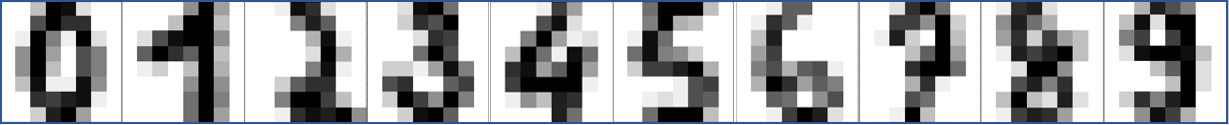

Optical character recognition (OCR) is a technology that enables the recognition of text characters in digital images. This technology can be used to automatically convert scanned documents, pictures, or other digital images that contain text into machine-readable text.

Random forest is a type of machine learning algorithm that is commonly used in the field of OCR. This algorithm is an ensemble method that involves training multiple decision tree classifiers on subsets of the data and then averaging the predictions of all the individual classifiers to make a final prediction.

In the context of OCR, a random forest classifier can be trained to recognize text characters in images by learning from a large dataset of labeled images. The classifier is presented with many examples of each character, and uses these examples to learn the visual patterns that are associated with each character.

Once the classifier has been trained, it can be used to make predictions on new images. Given an image of a text character, the classifier will analyze the visual patterns in the image and make a prediction about which character is most likely to be present.

Dataset: [Data Sets for Deep Learning - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/deeplearning/ug/data-sets-for-deep-learning.html)

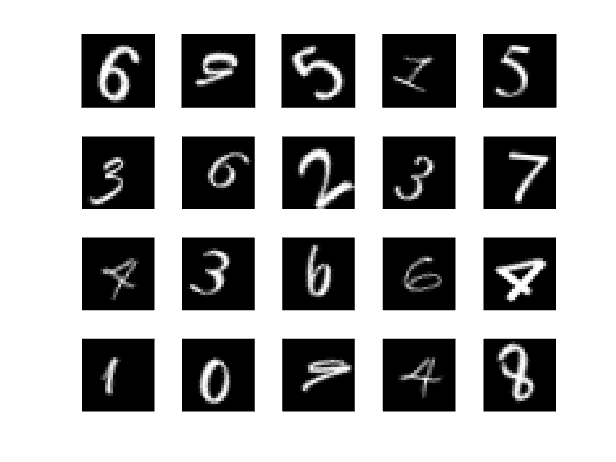

% Import dataset of numbers
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

% Show example of dataset
figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

n_samples = length(imds.Files);

% Extract the images into a matrix
X_data = [];
for i = 1:n_samples
    X_data = [X_data; reshape(readimage(imds,i)',[1,28*28])];
end

% Save the labels of the images
Y_data = imds.Labels(1:n_samples);

% Split the data 50% training adn 50% testing
[trainInd,valInd,testInd] = dividerand(n_samples,0.5,0,0.5);

X_Train = X_data(trainInd,:);
X_Test = X_data(testInd,:);
Y_Train = Y_data(trainInd,:);
Y_Test = Y_data(testInd,:);

% Create fit
classifier = TreeBagger(10,array2table(im2double(X_Train)),Y_Train,'NumPredictorsToSample',70);

% Evaluate the model performance on the test set
y_pred = predict(classifier,array2table(im2double(X_Test)));
accuracy = mean(y_pred == Y_Test);
fprintf("Accuracy: %.2f\n", accuracy);

Accuracy: 0.96


Below is an example that also shows a number from the test set that is evaluated with the .

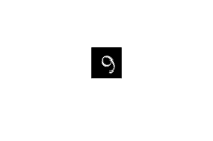

tbl = [array2table(im2double(X_Train)), array2table(Y_Train)];

% Select random nummber image
n = randi([0,n_samples],1);
figure;
imshow(imds.Files{n})

reshape(readimage(imds,n)',[1,28*28]);

% Predict number based on image
yp = predict(classifier,im2double(reshape(readimage(imds,n)',[1,28*28])));
disp(['Predicted:',categorical(yp)])

     Predicted:      9 

